%Ex1 Lead Design
kc=10; 
G=tf([4],[1 2 0])


G =
 
      4
  ---------
  s^2 + 2 s
 
Continuous-time transfer function.


G1 = kc*G


G1 =
 
     40
  ---------
  s^2 + 2 s
 
Continuous-time transfer function.


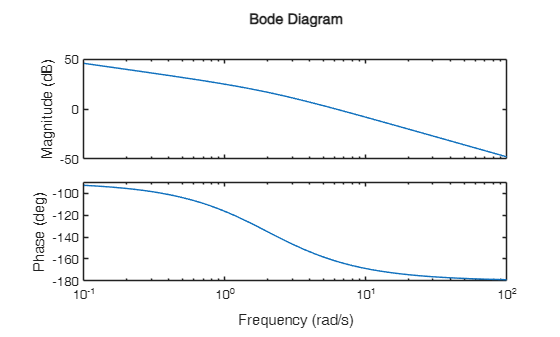

bode(G1)

[Gm,Pm,Wcg,Wcp] = margin(G1)

Gm = Inf

Pm = 17.9642

Wcg = Inf

Wcp = 6.1685

GmdB = 20*log10(Gm)

GmdB = Inf

% Design Lead
phi=38;
alfa=(1-sind(phi))/(1+sind(phi))

alfa = 0.2379

dB=-20*log10(1/sqrt(alfa))

dB = -6.2364

wgdat=9

wgdat = 9

zl=wgdat*sqrt(alfa)

zl = 4.3896

pl=zl/alfa

pl = 18.4527

klead=1/alfa

klead = 4.2037

Glead=zpk(-zl,-pl,klead)


Glead =
 
  4.2037 (s+4.39)
  ---------------
     (s+18.45)
 
Continuous-time zero/pole/gain model.


GleadG1=Glead*G1


GleadG1 =
 
   168.15 (s+4.39)
  -----------------
  s (s+18.45) (s+2)
 
Continuous-time zero/pole/gain model.


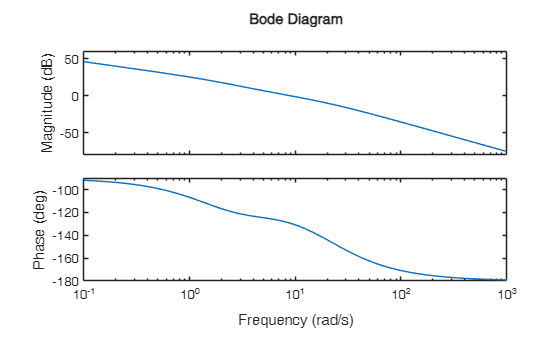

bode(GleadG1)

[Gm,Pm,Wcg,Wcp] = margin(GleadG1)

Gm = Inf

Pm = 50.6342

Wcg = Inf

Wcp = 8.9217

GmdB = 20*log10(Gm)

GmdB = Inf

%Step response
sys1 = feedback(G,1)


sys1 =
 
        4
  -------------
  s^2 + 2 s + 4
 
Continuous-time transfer function.


sys2 = feedback(GleadG1,1)


sys2 =
 
         168.15 (s+4.39)
  ------------------------------
  (s+6.421) (s^2 + 14.03s + 115)
 
Continuous-time zero/pole/gain model.


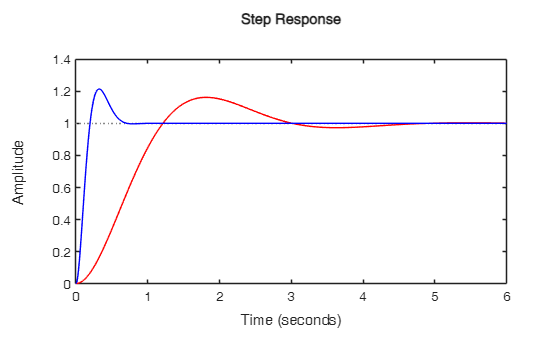

h = stepplot(sys1,'r',sys2,'b');

stepinfo(sys2)

ans = struct with fields:
         RiseTime: 0.1338
    TransientTime: 0.6176
     SettlingTime: 0.6176
      SettlingMin: 0.9005
      SettlingMax: 1.2155
        Overshoot: 21.5465
       Undershoot: 0
             Peak: 1.2155
         PeakTime: 0.3228


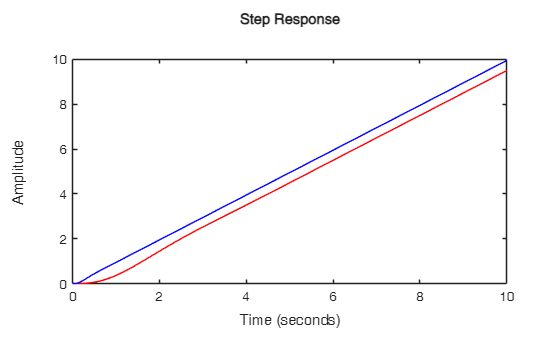

% Ramp response
s = tf('s');
h = stepplot(10,sys1/s,'r',sys2/s,'b');

%Ex2 Lead Design
kc=10;
G=tf([1],[1 0 0])


G =
 
   1
  ---
  s^2
 
Continuous-time transfer function.


G1 = kc*G


G1 =
 
  10
  ---
  s^2
 
Continuous-time transfer function.


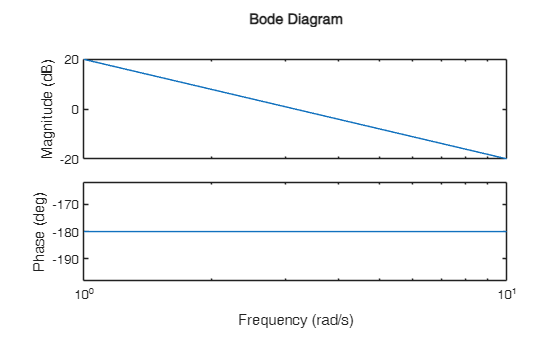

bode(G1)

[Gm,Pm,Wcg,Wcp] = margin(G1)

Gm = 1.0000

Pm = 0

Wcg = 3.1623

Wcp = 3.1623

GmdB = 20*log10(Gm)

GmdB = 1.9287e-15

% Design Lead
phi=55;
alfa=(1-sind(phi))/(1+sind(phi))

alfa = 0.0994

dB=-20*log10(1/sqrt(alfa))

dB = -10.0256

wgdat=5.63

wgdat = 5.6300

zl=wgdat*sqrt(alfa)

zl = 1.7751

pl=zl/alfa

pl = 17.8561

klead=1/alfa

klead = 10.0590

Glead=zpk(-zl,-pl,klead)


Glead =
 
  10.059 (s+1.775)
  ----------------
     (s+17.86)
 
Continuous-time zero/pole/gain model.


GleadG1=Glead*G1


GleadG1 =
 
  100.59 (s+1.775)
  ----------------
   s^2 (s+17.86)
 
Continuous-time zero/pole/gain model.


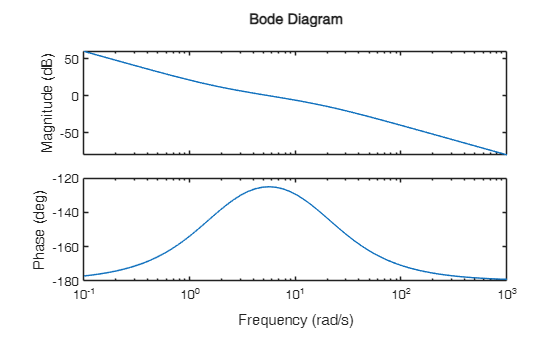

bode(GleadG1)

[Gm,Pm,Wcg,Wcp] = margin(GleadG1)

Gm = 0

Pm = 55.0000

Wcg = 0

Wcp = 5.6329

GmdB = 20*log10(Gm)

GmdB = -Inf

%Step response
sys1 = feedback(G,1)


sys1 =
 
     1
  -------
  s^2 + 1
 
Continuous-time transfer function.


sys2 = feedback(GleadG1,1)


sys2 =
 
        100.59 (s+1.775)
  -----------------------------
  (s+3.719) (s+5.673) (s+8.465)
 
Continuous-time zero/pole/gain model.


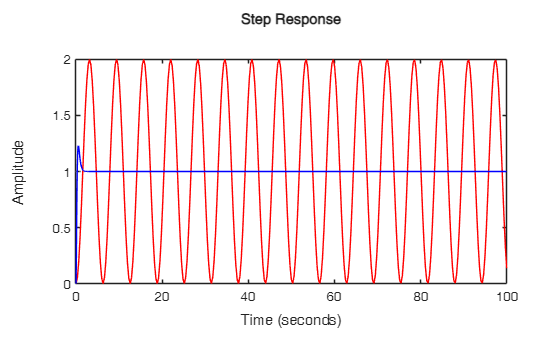

h = stepplot(100,sys1,'r',sys2,'b');

stepinfo(sys2)

ans = struct with fields:
         RiseTime: 0.2017
    TransientTime: 1.4836
     SettlingTime: 1.4836
      SettlingMin: 0.9247
      SettlingMax: 1.2310
        Overshoot: 23.1035
       Undershoot: 0
             Peak: 1.2310
         PeakTime: 0.5441


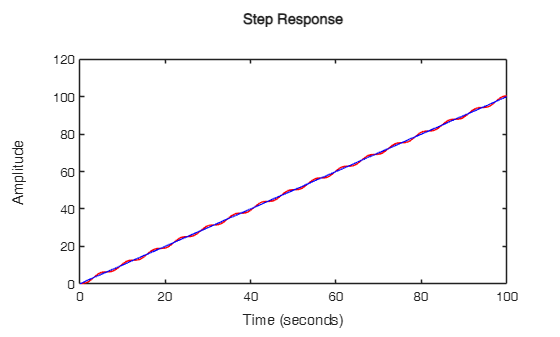

% Ramp response
s = tf('s');
h = stepplot(100,sys1/s,'r',sys2/s,'b');

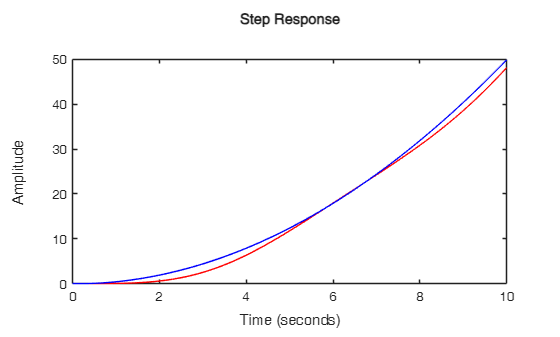

% Parabolic
h = stepplot(10,sys1/s^2,'r',sys2/s^2,'b');

%Ex3 Lag Design
kc=2; 
G=tf([20],[1 2 0])


G =
 
     20
  ---------
  s^2 + 2 s
 
Continuous-time transfer function.


G1 = kc*G


G1 =
 
     40
  ---------
  s^2 + 2 s
 
Continuous-time transfer function.


bode(G1)

[Gm,Pm,Wcg,Wcp] = margin(G1)

Gm = Inf

Pm = 17.9642

Wcg = Inf

Wcp = 6.1685

GmdB = 20*log10(Gm)

GmdB = Inf

% Design Lag
dB=25;
beta=10^(dB/20)

beta = 17.7828

wgdat = 1

wgdat = 1

zlag=wgdat/10;
plag=zlag/beta

plag = 0.0056

Glag=zpk(-zlag,-plag,1/beta)


Glag =
 
  0.056234 (s+0.1)
  ----------------
    (s+0.005623)
 
Continuous-time zero/pole/gain model.


GlagG1=Glag*G1


GlagG1 =
 
     2.2494 (s+0.1)
  --------------------
  s (s+0.005623) (s+2)
 
Continuous-time zero/pole/gain model.


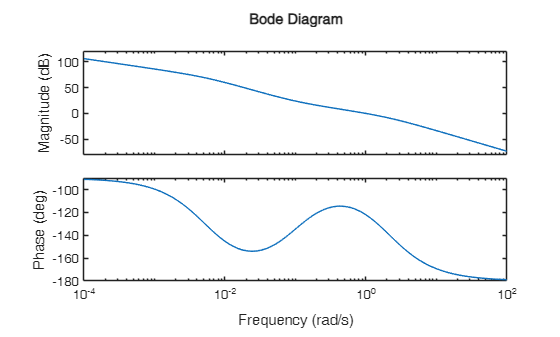

% Bode plot
bode(GlagG1)

[Gm,Pm,Wcg,Wcp] = margin(GlagG1)

Gm = Inf

Pm = 57.8879

Wcg = Inf

Wcp = 1.0090

GmdB = 20*log10(Gm)

GmdB = Inf

%Step response
sys1 = feedback(G,1)


sys1 =
 
        20
  --------------
  s^2 + 2 s + 20
 
Continuous-time transfer function.


sys2 = feedback(GlagG1,1)


sys2 =
 
           2.2494 (s+0.1)
  ---------------------------------
  (s+0.1096) (s^2 + 1.896s + 2.053)
 
Continuous-time zero/pole/gain model.


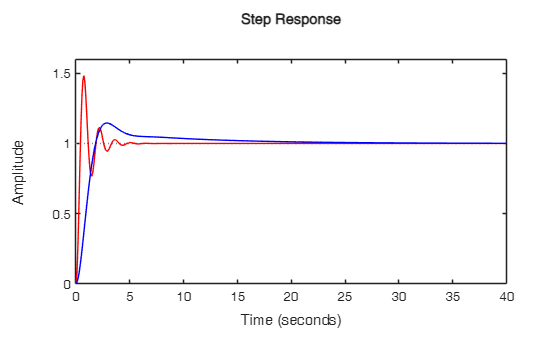

h = stepplot(40,sys1,'r',sys2,'b');

stepinfo(sys2)

ans = struct with fields:
         RiseTime: 1.2345
    TransientTime: 15.2045
     SettlingTime: 15.2045
      SettlingMin: 0.9165
      SettlingMax: 1.1462
        Overshoot: 14.6221
       Undershoot: 0
             Peak: 1.1462
         PeakTime: 2.8660


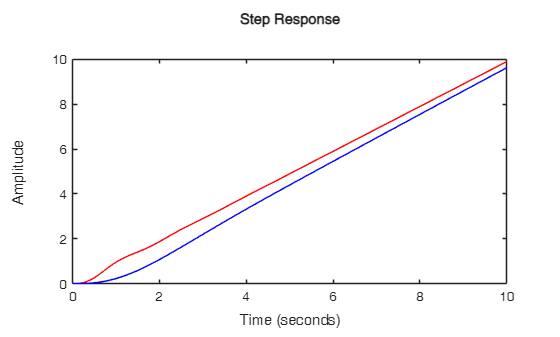

% Ramp response
s = tf('s');
h = stepplot(10,sys1/s,'r',sys2/s,'b');

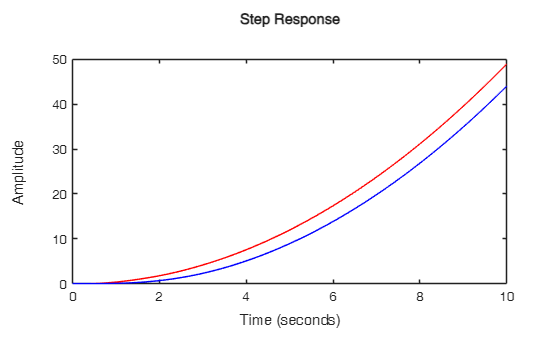

% Parabolic
h = stepplot(10,sys1/s^2,'r',sys2/s^2,'b');

%Ex4 Lag Design
kc=5; 
G=tf([100],[1 15 50 0])


G =
 
          100
  -------------------
  s^3 + 15 s^2 + 50 s
 
Continuous-time transfer function.


G1 = kc*G


G1 =
 
          500
  -------------------
  s^3 + 15 s^2 + 50 s
 
Continuous-time transfer function.


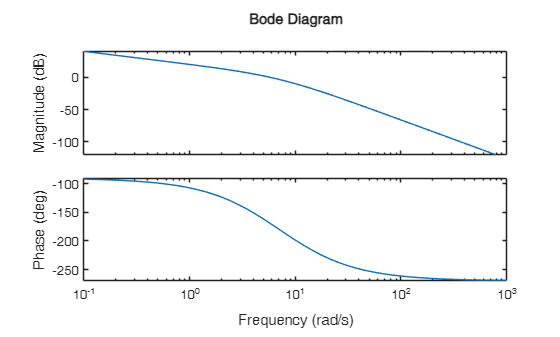

bode(G1)

[Gm,Pm,Wcg,Wcp] = margin(G1)

Gm = 1.5000

Pm = 11.4304

Wcg = 7.0711

Wcp = 5.7154

GmdB = 20*log10(Gm)

GmdB = 3.5218

% Design Lag
dB=19.8;
beta=10^(dB/20)

beta = 9.7724

wgdat = 1

wgdat = 1

zlag=wgdat/10;
plag=zlag/beta

plag = 0.0102

Glag=zpk(-zlag,-plag,1/beta)


Glag =
 
  0.10233 (s+0.1)
  ---------------
    (s+0.01023)
 
Continuous-time zero/pole/gain model.


GlagG1=Glag*G1


GlagG1 =
 
        51.165 (s+0.1)
  --------------------------
  s (s+0.01023) (s+5) (s+10)
 
Continuous-time zero/pole/gain model.


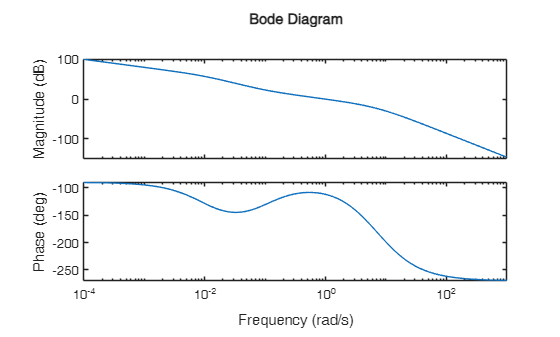

% Bode plot
bode(GlagG1)

[Gm,Pm,Wcg,Wcp] = margin(GlagG1)

Gm = 14.2634

Pm = 67.8182

Wcg = 6.9752

Wcp = 1.0032

GmdB = 20*log10(Gm)

GmdB = 23.0844

%Step response
sys1 = feedback(G,1)


sys1 =
 
             100
  -------------------------
  s^3 + 15 s^2 + 50 s + 100
 
Continuous-time transfer function.


sys2 = feedback(GlagG1,1)


sys2 =
 
                51.165 (s+0.1)
  -------------------------------------------
  (s+10.81) (s+0.1105) (s^2 + 4.092s + 4.285)
 
Continuous-time zero/pole/gain model.


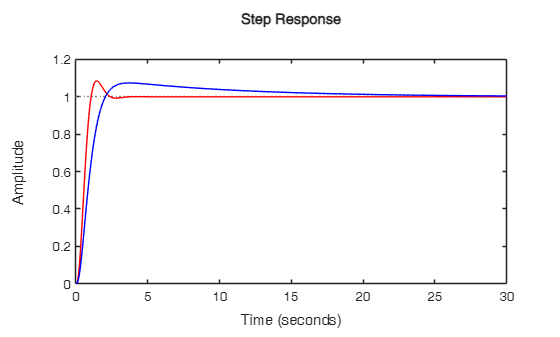

h = stepplot(30,sys1,'r',sys2,'b');

stepinfo(sys2)

ans = struct with fields:
         RiseTime: 1.2769
    TransientTime: 16.0535
     SettlingTime: 16.0535
      SettlingMin: 0.9067
      SettlingMax: 1.0738
        Overshoot: 7.3847
       Undershoot: 0
             Peak: 1.0738
         PeakTime: 3.6918


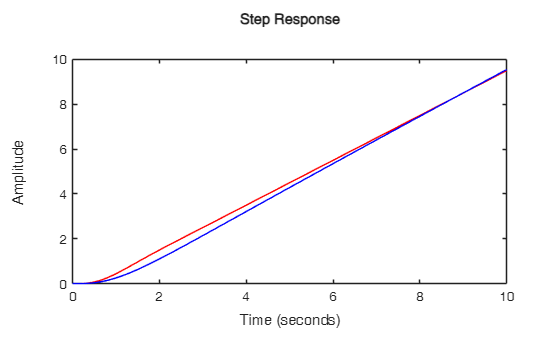

% Ramp response
s = tf('s');
h = stepplot(10,sys1/s,'r',sys2/s,'b');

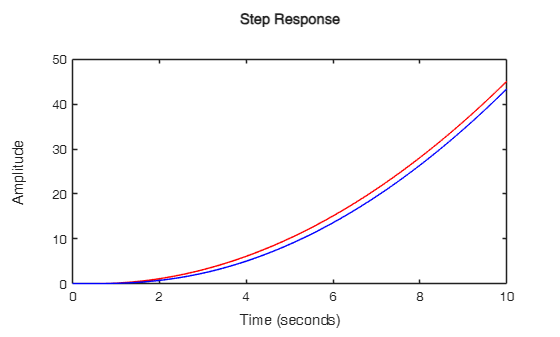

% Parabolic
h = stepplot(10,sys1/s^2,'r',sys2/s^2,'b');

%Ex5 Lead Lag Design
syms s
Gd = s*(s+1)*(s+5)

$$Gd = s\,\left(s+1\right)\,\left(s+5\right)$$

expand(Gd)

$$ans = s^{3}+6\,s^{2}+5\,s$$

G=tf([10],[1 6 5 0])


G =
 
         10
  -----------------
  s^3 + 6 s^2 + 5 s
 
Continuous-time transfer function.


% Kv =20, phase  margin > 50 deg., gain margin > 10dB
Kc= 20*5/10

Kc = 10

G1 = Kc*G


G1 =
 
         100
  -----------------
  s^3 + 6 s^2 + 5 s
 
Continuous-time transfer function.


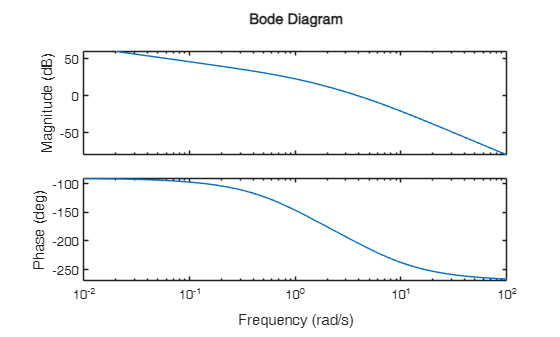

bode(G1)

[Gm,Pm,Wcg,Wcp] = margin(G1)

Gm = 0.3000

Pm = -23.6504

Wcg = 2.2361

Wcp = 3.9073

GmdB = 20*log10(Gm)

GmdB = -10.4576


% Design Lead Compensator
phi=55;
alfa=(1-sind(phi))/(1+sind(phi))

alfa = 0.0994

dB=-20*log10(1/sqrt(alfa))

dB = -10.0256

wlead=6.26

wlead = 6.2600

zl=wlead*sqrt(alfa)

zl = 1.9738

pl=zl/alfa

pl = 19.8542

klead=1/alfa

klead = 10.0590

Glead=zpk(-zl,-pl,klead)


Glead =
 
  10.059 (s+1.974)
  ----------------
     (s+19.85)
 
Continuous-time zero/pole/gain model.


GleadG1=Glead*G1


GleadG1 =
 
     1005.9 (s+1.974)
  -----------------------
  s (s+19.85) (s+5) (s+1)
 
Continuous-time zero/pole/gain model.


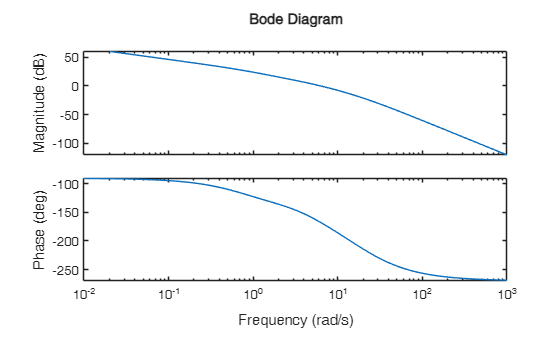

bode(GleadG1)

[Gm,Pm,Wcg,Wcp] = margin(GleadG1)

Gm = 1.8466

Pm = 12.7425

Wcg = 8.6996

Wcp = 6.2513

GmdB = 20*log10(Gm)

GmdB = 5.3273


% Design Lag Compensator
dBLag=23.85

dBLag = 23.8500

beta=10^(dBLag/20)

beta = 15.5776

wlag=1

wlag = 1

zg=wlag/10

zg = 0.1000

pg=zg/beta

pg = 0.0064

klag=1/beta

klag = 0.0642

Glag=zpk(-zg,-pg,klag)


Glag =
 
  0.064195 (s+0.1)
  ----------------
    (s+0.006419)
 
Continuous-time zero/pole/gain model.


GleadGlagG1=Glead*Glag*G1


GleadGlagG1 =
 
        64.574 (s+1.974) (s+0.1)
  ------------------------------------
  s (s+19.85) (s+5) (s+1) (s+0.006419)
 
Continuous-time zero/pole/gain model.


GleadGlag=Glead*Glag


GleadGlag =
 
  0.64574 (s+1.974) (s+0.1)
  -------------------------
   (s+19.85) (s+0.006419)
 
Continuous-time zero/pole/gain model.


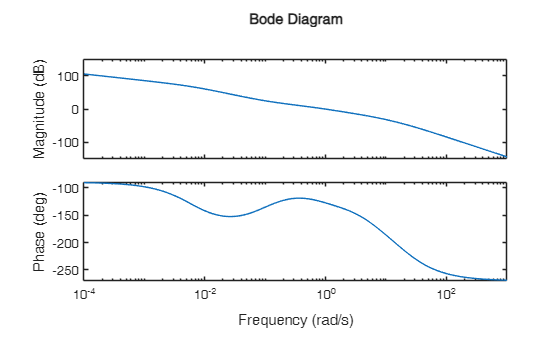

bode(GleadGlagG1)

[Gm,Pm,Wcg,Wcp] = margin(GleadGlagG1)

Gm = 27.8990

Pm = 52.3155

Wcg = 8.5642

Wcp = 1.0012

GmdB = 20*log10(Gm)

GmdB = 28.9118

%Step response
sys1 = feedback(G,1)


sys1 =
 
            10
  ----------------------
  s^3 + 6 s^2 + 5 s + 10
 
Continuous-time transfer function.


sys2 = feedback(GleadGlagG1,1)


sys2 =
 
                64.574 (s+1.974) (s+0.1)
  ----------------------------------------------------
  (s+20.06) (s+4.335) (s+0.1078) (s^2 + 1.362s + 1.36)
 
Continuous-time zero/pole/gain model.


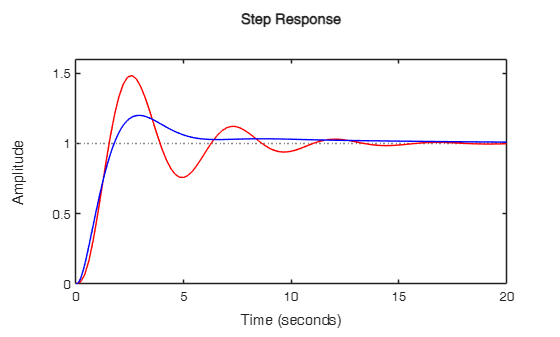

h = stepplot(20,sys1,'r',sys2,'b');

stepinfo(sys2)

ans = struct with fields:
         RiseTime: 1.2054
    TransientTime: 13.3141
     SettlingTime: 13.3141
      SettlingMin: 0.9017
      SettlingMax: 1.2003
        Overshoot: 20.0295
       Undershoot: 0
             Peak: 1.2003
         PeakTime: 2.9319


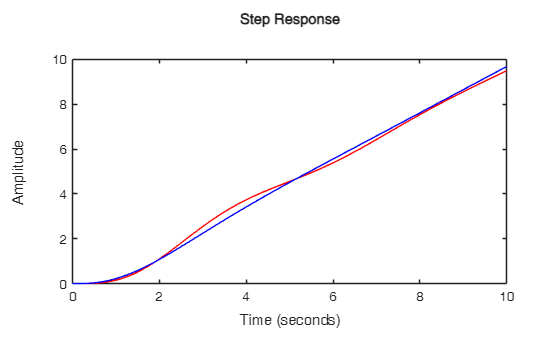

% Ramp response
s = tf('s');
h = stepplot(10,sys1/s,'r',sys2/s,'b');

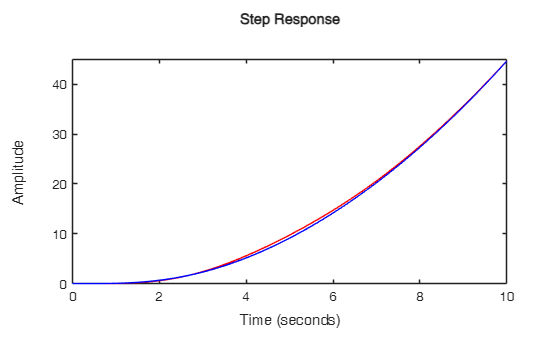

% Parabolic
h = stepplot(10,sys1/s^2,'r',sys2/s^2,'b');

% PID Controller Design
syms s KP KI KD K
format bank
Gp = 1/(s*(s+1)*(s+10))

$$Gp = \frac{1}{s\,\left(s+1\right)\,\left(s+10\right)}$$

expand(Gp)

$$ans = \frac{1}{s^{3}+11\,s^{2}+10\,s}$$

Gp = tf([1],[1 11 10 0])


Gp =
 
           1
  -------------------
  s^3 + 11 s^2 + 10 s
 
Continuous-time transfer function.


% parabolic sst err. spec. <= 0.5
% SO <= 40%
K = 20;
Mfd = 35;
s = tf('s');
G = K*Gp/s


G =
 
           20
  ---------------------
  s^4 + 11 s^3 + 10 s^2
 
Continuous-time transfer function.


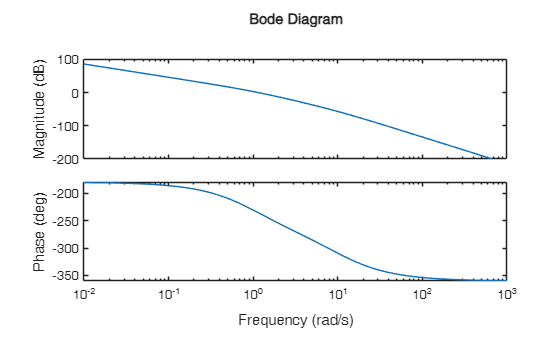

bode(G)

[Gm,Pm,Wcg,Wcp] = margin(G)

Gm =              0


Pm =         -55.36


Wcg =              0


Wcp =           1.14


GmdB = 20*log10(Gm)

GmdB =           -Inf


% Design 2 PD controller
T1 = (tand(55))/1.2

T1 =           1.19


T2 = T1

T2 =           1.19


Kc = K*(T1+T2)

Kc =          47.60


Ti = T1+T2

Ti =           2.38


Td = T1*T2/(T1+T2)

Td =           0.60



Gc1 = K/s*(1+T1*s)*(1+T2*s)


Gc1 =
 
  28.33 s^2 + 47.6 s + 20
  -----------------------
             s
 
Continuous-time transfer function.



L = Gc1*Gp % Loop transfer function with PID controller.


L =
 
  28.33 s^2 + 47.6 s + 20
  -----------------------
   s^4 + 11 s^3 + 10 s^2
 
Continuous-time transfer function.


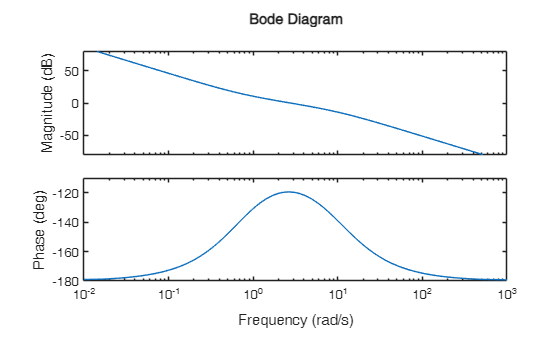

bode(L)

[Gm,Pm,Wcg,Wcp] = margin(L)

Gm =              0


Pm =          60.60


Wcg =              0


Wcp =           2.80


GmdB = 20*log10(Gm)

GmdB =           -Inf


% Closed-loop transfer function with PID controller
sys1 = feedback(L,1)


sys1 =
 
         28.33 s^2 + 47.6 s + 20
  --------------------------------------
  s^4 + 11 s^3 + 38.33 s^2 + 47.6 s + 20
 
Continuous-time transfer function.


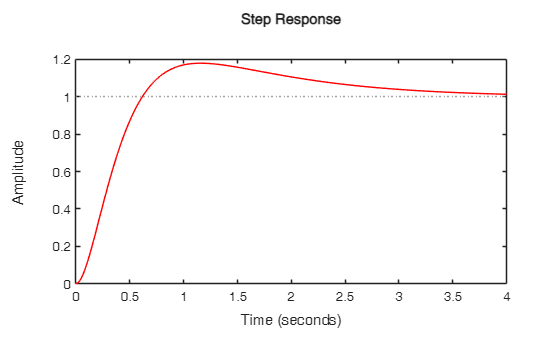

h = stepplot(4,sys1,'r');

stepinfo(sys1)

ans = struct with fields:
         RiseTime: 0.42
    TransientTime: 3.63
     SettlingTime: 3.63
      SettlingMin: 0.90
      SettlingMax: 1.18
        Overshoot: 17.95
       Undershoot: 0
             Peak: 1.18
         PeakTime: 1.15


wcdat = 0.4;
diff_Mf = 75;
wcdat_tao2 = atand(diff_Mf)

wcdat_tao2 =          89.24


tao2 = 2.3

tao2 =           2.30


K = 10^(0.72/20)  

K =           1.09


Ti = 10/wcdat

Ti =          25.00


% Exercise
%Ex5 Lead Lag Design
syms s
Gd = s*(s+1)*(s+5)

$$Gd = s\,\left(s+1\right)\,\left(s+5\right)$$

expand(Gd)

$$ans = s^{3}+6\,s^{2}+5\,s$$

G=tf([10],[1 6 5 0])


G =
 
         10
  -----------------
  s^3 + 6 s^2 + 5 s
 
Continuous-time transfer function.


kc=2.5

kc =           2.50


G1 = kc*G


G1 =
 
         25
  -----------------
  s^3 + 6 s^2 + 5 s
 
Continuous-time transfer function.


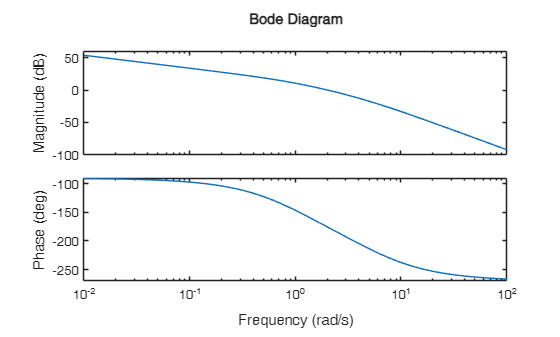

bode(G1)

[Gm,Pm,Wcg,Wcp] = margin(G1)

Gm =           1.20


Pm =           3.94


Wcg =           2.24


Wcp =           2.04


GmdB = 20*log10(Gm)

GmdB =           1.58



% Design Lead Compensator
phi=51;
alfa=(1-sind(phi))/(1+sind(phi))

alfa =           0.13


dB=-20*log10(1/sqrt(alfa))

dB =          -9.02


wlead=3.35

wlead =           3.35


zl=wlead*sqrt(alfa)

zl =           1.19


pl=zl/alfa

pl =           9.46


klead=1/alfa

klead =           7.97


Glead=zpk(-zl,-pl,klead)


Glead =
 
  7.9745 (s+1.186)
  ----------------
      (s+9.46)
 
Continuous-time zero/pole/gain model.


GleadG1=Glead*G1


GleadG1 =
 
     199.36 (s+1.186)
  ----------------------
  s (s+9.46) (s+5) (s+1)
 
Continuous-time zero/pole/gain model.


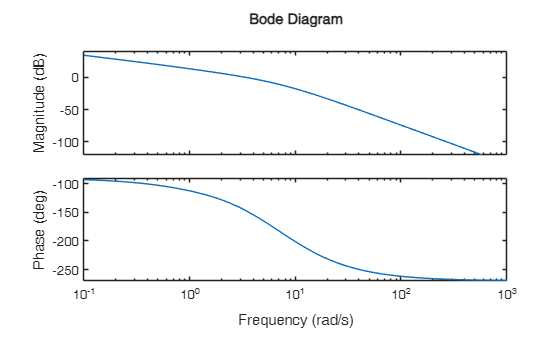

bode(GleadG1)

[Gm,Pm,Wcg,Wcp] = margin(GleadG1)

Gm =           3.23


Pm =          33.75


Wcg =           6.68


Wcp =           3.35


GmdB = 20*log10(Gm)

GmdB =          10.18



% Design Lag Compensator
dBLag=13

dBLag =          13.00


beta=10^(dBLag/20)

beta =           4.47


wlag=1

wlag =           1.00


zg=wlag/10

zg =           0.10


pg=zg/beta

pg =           0.02


klag=1/beta

klag =           0.22


Glag=zpk(-zg,-pg,klag)


Glag =
 
  0.22387 (s+0.1)
  ---------------
    (s+0.02239)
 
Continuous-time zero/pole/gain model.


GleadGlagG1=Glead*Glag*G1


GleadGlagG1 =
 
       44.632 (s+1.186) (s+0.1)
  ----------------------------------
  s (s+9.46) (s+5) (s+1) (s+0.02239)
 
Continuous-time zero/pole/gain model.


GleadGlag=Glead*Glag


GleadGlag =
 
  1.7853 (s+1.186) (s+0.1)
  ------------------------
    (s+9.46) (s+0.02239)
 
Continuous-time zero/pole/gain model.


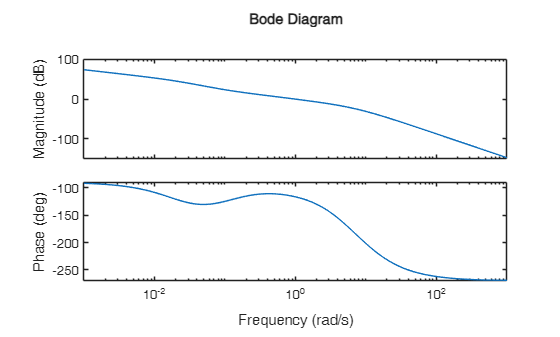

bode(GleadGlagG1)

[Gm,Pm,Wcg,Wcp] = margin(GleadGlagG1)

Gm =          14.06


Pm =          63.19


Wcg =           6.60


Wcp =           1.01


GmdB = 20*log10(Gm)

GmdB =          22.96


%Step response
sys1 = feedback(G,1)


sys1 =
 
            10
  ----------------------
  s^3 + 6 s^2 + 5 s + 10
 
Continuous-time transfer function.


sys2 = feedback(GleadGlagG1,1)


sys2 =
 
                44.632 (s+1.186) (s+0.1)
  -----------------------------------------------------
  (s+10.26) (s+2.955) (s+0.1078) (s^2 + 2.156s + 1.619)
 
Continuous-time zero/pole/gain model.


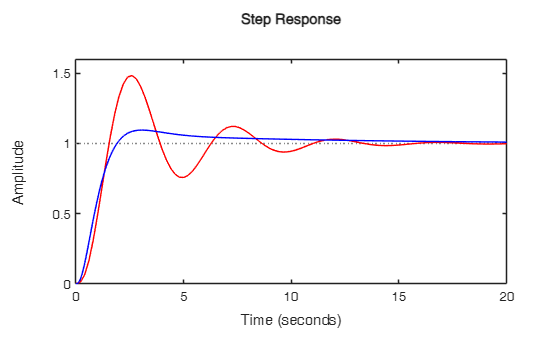

h = stepplot(20,sys1,'r',sys2,'b');

stepinfo(sys2)

ans = struct with fields:
         RiseTime: 1.23
    TransientTime: 13.56
     SettlingTime: 13.56
      SettlingMin: 0.91
      SettlingMax: 1.10
        Overshoot: 9.55
       Undershoot: 0
             Peak: 1.10
         PeakTime: 3.05


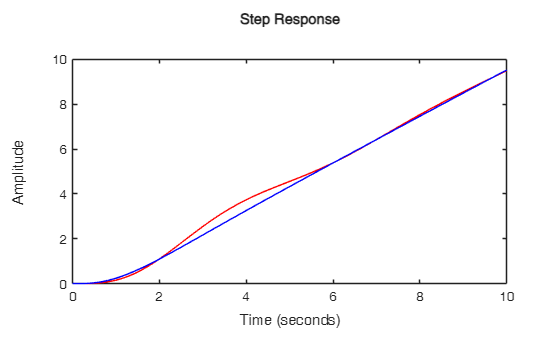

% Ramp response
s = tf('s');
h = stepplot(10,sys1/s,'r',sys2/s,'b');

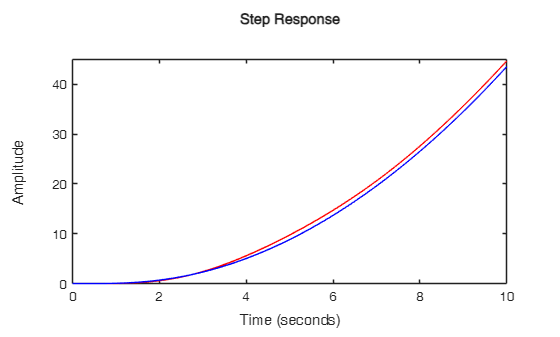

% Parabolic
h = stepplot(10,sys1/s^2,'r',sys2/s^2,'b');